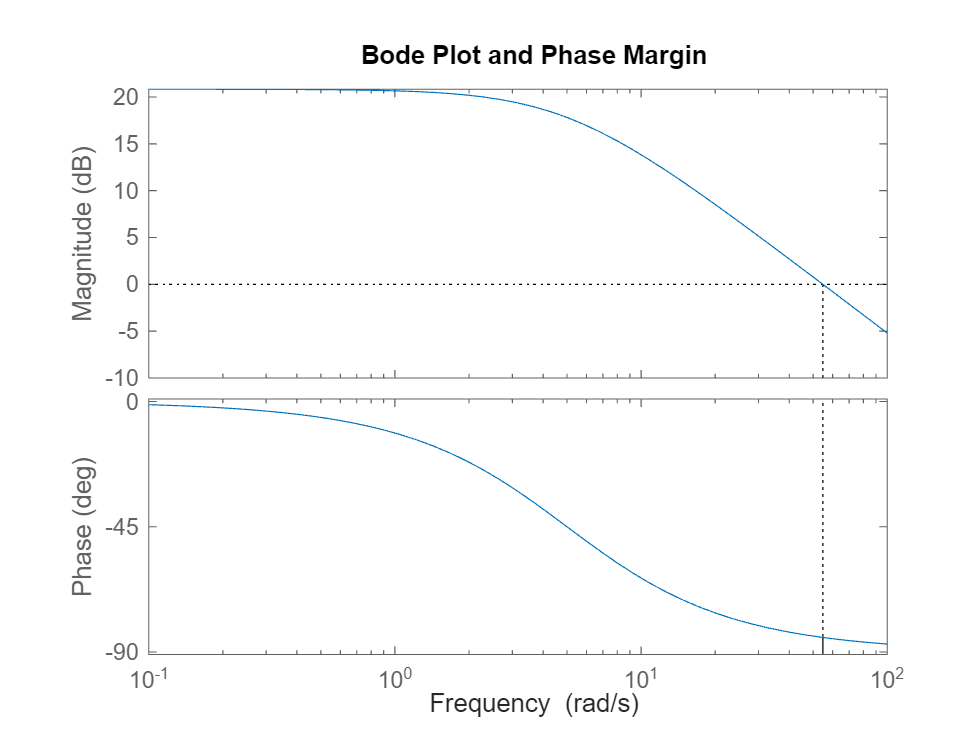

% Define the plant transfer function
s = tf('s');
G_s = 1 / (0.2 * s + 1);

% Define the range of gain K
K = 11;

% Open-loop transfer function
G_open = K * G_s;

% Closed-loop transfer function
G_closed = feedback(G_open, 1); % Unity feedback

% Plot Bode plot to check phase margin
figure;
margin(G_open);
title('Bode Plot and Phase Margin');


% Display steady-state error for ramp input
Kv = K / 0.2; % Velocity error constant
ess_ramp = 1 / Kv; % Steady-state error for ramp input

fprintf('Velocity error constant (Kv): %f\n', Kv);

Velocity error constant (Kv): 55.000000


fprintf('Steady-state error for ramp input: %f\n', ess_ramp);

Steady-state error for ramp input: 0.018182


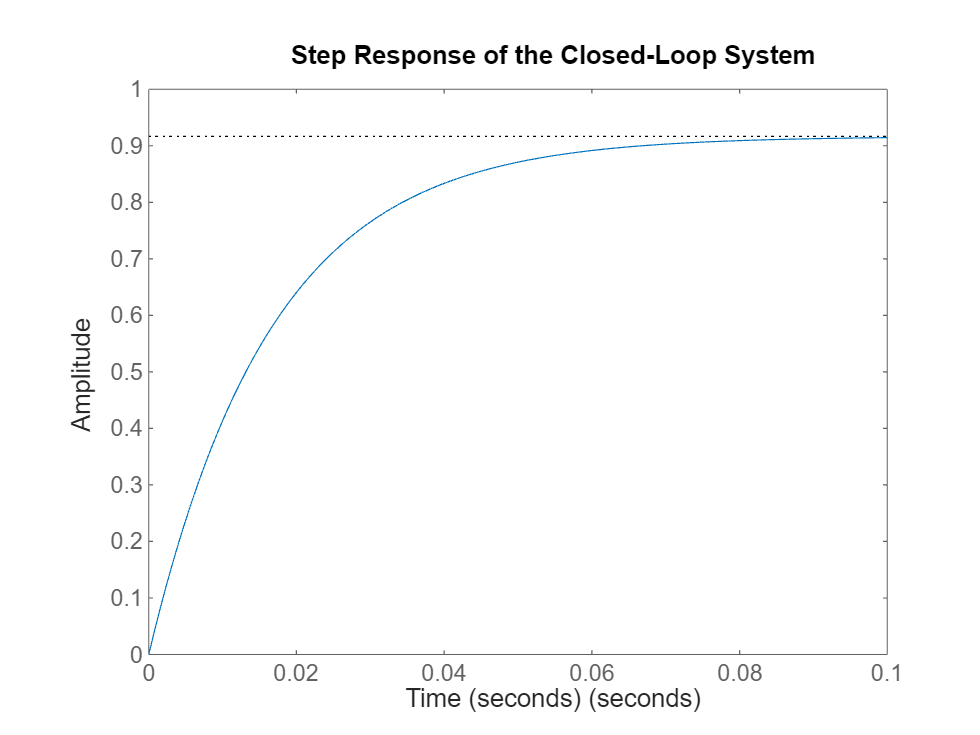


% Plot step response
figure;
step(G_closed);
title('Step Response of the Closed-Loop System');
xlabel('Time (seconds)');

ylabel('Amplitude');

% Check phase margin
[Gm, Pm, Wcg, Wcp] = margin(G_open); % Gain margin (Gm), Phase margin (Pm)
fprintf('Phase margin: %f degrees\n', Pm);

Phase margin: 95.215909 degrees



% Ensure that the conditions are met
if ess_ramp < 0.02 && Pm > 48
    disp('The design meets both the steady-state error and phase margin requirements.');
else
    disp('The design does not meet one or both of the requirements. Adjust K or controller design.');
end

The design meets both the steady-state error and phase margin requirements.
